## Frequency resolution, Zero Padding (time domain) 

### A)

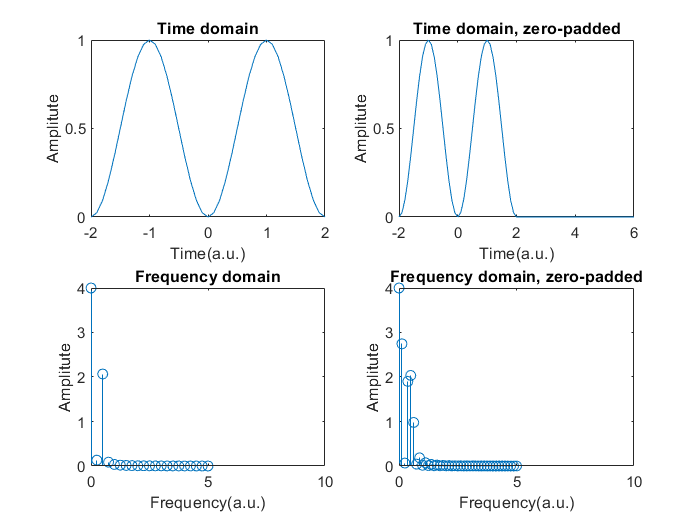

clear all

tmin = -2;
tmax = 2;
sampling_rate = 10;

npts = (tmax-tmin)*sampling_rate + 1;
t_values = tmin:(1/sampling_rate):tmax;

x = sin(0.5*pi*t_values).^2;

figure

subplot(2,2,1)
plot(t_values, x)
title('Time domain')
xlabel('Time(a.u.)')
ylabel('Amplitute')

X = fft(x);
f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts);

subplot(2,2,3)
stem(f_shifted_values, 2*fftshift(abs(X))/sampling_rate)
title('Frequency domain')
xlabel('Frequency(a.u.)')
ylabel('Amplitute')
xlim([0 10])



tmin2 = -2;
tmax2 = 6;

npts2 = (tmax2-tmin2)*sampling_rate + 1;
t_values2 = tmin2:(1/sampling_rate):tmax2;
x2 = [x zeros(1, 40)];

subplot(2,2,2)
plot(t_values2 , x2)
title('Time domain, zero-padded')
xlabel('Time(a.u.)')
ylabel('Amplitute')

X2 = fft(x2);
f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts2);

subplot(2,2,4)
stem(f_shifted_values, 2*fftshift(abs(X2))/sampling_rate)
title('Frequency domain, zero-padded')
xlabel('Frequency(a.u.)')
ylabel('Amplitute')
xlim([0 10])

### B)

You can interpolate the DFT by zero padding. Zero padding enables you to obtain more accurate amplitude estimates of resolvable signal components without improving the frequency resolution of the DFT.

The frequency resolution of each spectral line is **equal to the Sampling Rate divided by the FFT size.**

### C)

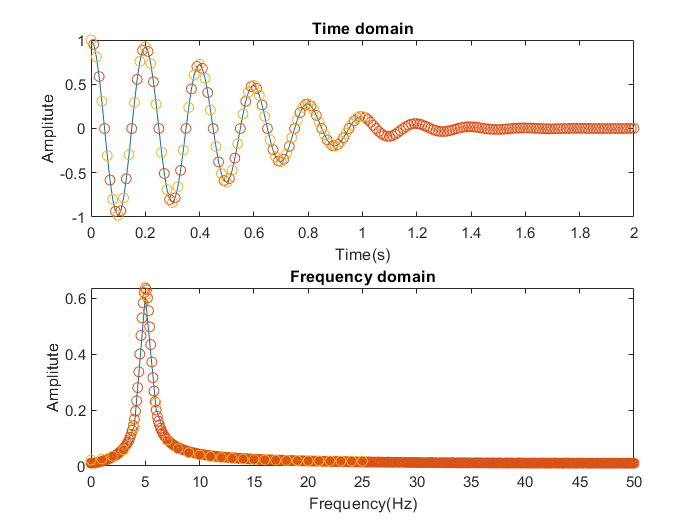

clear all

tmin = [0, 0, 0];
tmax = [1, 10, 1];
sampling_rate = [100, 100, 50];
npts = [(tmax(1)-tmin(1))*sampling_rate(1) + 1, (tmax(2)-tmin(2))*sampling_rate(2) + 1, (tmax(3)-tmin(3))*sampling_rate(3) + 1];

t_values1 = tmin(1):(1/sampling_rate(1)):tmax(1);
t_values2 = tmin(2):(1/sampling_rate(2)):tmax(2);
t_values3 = tmin(3):(1/sampling_rate(3)):tmax(3);

x1 = cos(10*pi*t_values1) .* exp(-t_values1.^2/0.5);
x2 = cos(10*pi*t_values2) .* exp(-t_values2.^2/0.5);
x3 = cos(10*pi*t_values3) .* exp(-t_values3.^2/0.5);

figure

subplot(2,1,1)
plot(t_values1, x1)
title('Time domain')
xlabel('Time(s)')
ylabel('Amplitute')
xlim([0 2])
hold on
scatter(t_values2, x2)
scatter(t_values3, x3)
hold off

X1 = fft(x1);
X2 = fft(x2);
X3 = fft(x3);
f_shifted_values1 = linspace(-sampling_rate(1)/2, sampling_rate(1)/2, npts(1));
f_shifted_values2 = linspace(-sampling_rate(2)/2, sampling_rate(2)/2, npts(2));
f_shifted_values3 = linspace(-sampling_rate(3)/2, sampling_rate(3)/2, npts(3));


subplot(2,1,2)
plot(f_shifted_values1, 2*fftshift(abs(X1))/sampling_rate(1))
title('Frequency domain')
xlabel('Frequency(Hz)')
ylabel('Amplitute')
xlim([0 50])
hold on
scatter(f_shifted_values2, 2*fftshift(abs(X2))/sampling_rate(2))
scatter(f_shifted_values3, 2*fftshift(abs(X3))/sampling_rate(3))
hold off

freq. resolution1 = 100/101

freq. resolution2 = 100/1001

freq. resolution3 = 50/51

We can see that the second one is better in frequency domain than the others.

#### Extra point:

If you apply it over the entire length of the array, the length of the FFT would be the length of the array. But, the FFT is more efficient if the length is a power of two, so it is common to pad 0's onto the end of the signal until its length is a power of 2.

Overly simple example...

`x = [3.4, 2.56, 1.3]`

`x` has a length of 3, the next power of 2 after 3 is 4, so we change `x` to be

`x = [3.4, 2.56, 1.3, 0]`

and apply an FFT with length 4.

freq. resolution1 = 100/128

freq. resolution2 = 100/1024

freq. resolution3 = 50/64